clear

xMin = 0;
xMax = 1;
nELEM = 1;
eDegree = 1;


% Case A
exactSolution = computeExactSolution(1)

exactSolution = struct with fields:
         f: 1
       eqn: [1×1 symfun]
      cond: [1×2 sym]
    domain: [0 1]
         U: [1×1 symfun]


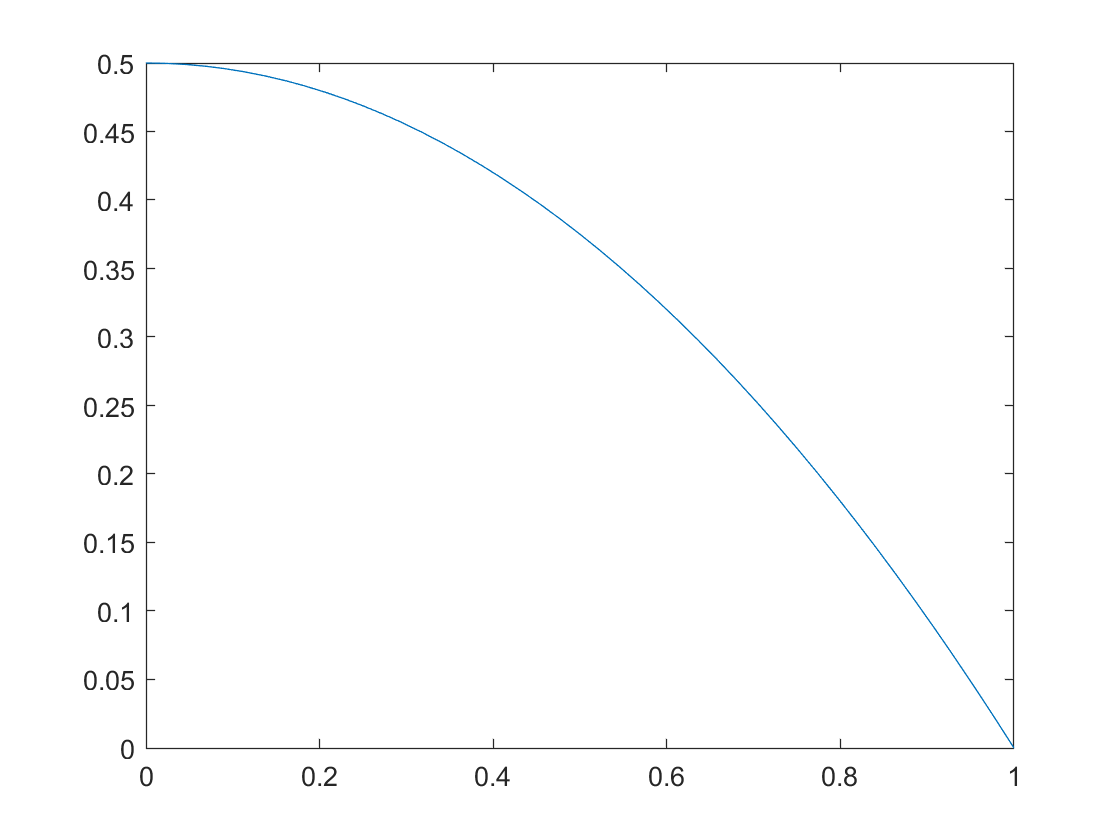

fplot(exactSolution.U,exactSolution.domain)

feSolution = main(nELEM,eDegree,1)

feSolution = struct with fields:
    Elements: [1×1 struct]
        Mesh: [1×1 struct]


## computeExactSolution()

figure
hold on

ELEM = feSolution.Elements

ELEM = struct with fields:
                          GDomain: [0 1]
                           GNodes: [0 1]
                             GDOF: [2×1 double]
                       GBasisFuns: [1×1 symfun]
                       GInterpFun: [1×1 symfun]
                          LDomain: [-1 1]
                           LNodes: [-1 1]
                             LDOF: [2×1 double]
                       LBasisFuns: [1×1 symfun]
                       LInterpFun: [1×1 symfun]
    GlobalVariate_to_LocalVariate: [1×1 symfun]
    LocalVariate_to_GlobalVariate: [1×1 symfun]


for e = 1:nELEM
    localExactSolution = exactSolution.U(ELEM(e).LocalVariate_to_GlobalVariate)
    localApproxSolution = ELEM(e).LBasisFuns' * ELEM(e).LDOF
    
    err(e) = int((localExactSolution - localApproxSolution)^2 , ELEM(e).LDomain)
    
    fplot(localExactSolution,ELEM(e).LDomain)
    fplot(ELEM(e).LBasisFuns' * ELEM(e).LDOF,[-1 1])
end

$$localExactSolution = \frac{1}{2}-\frac{{\left(\frac{x}{2}+\frac{1}{2}\right)}^{2}}{2}$$

$$localApproxSolution(x) = 1$$

$$err = \frac{14}{15}$$

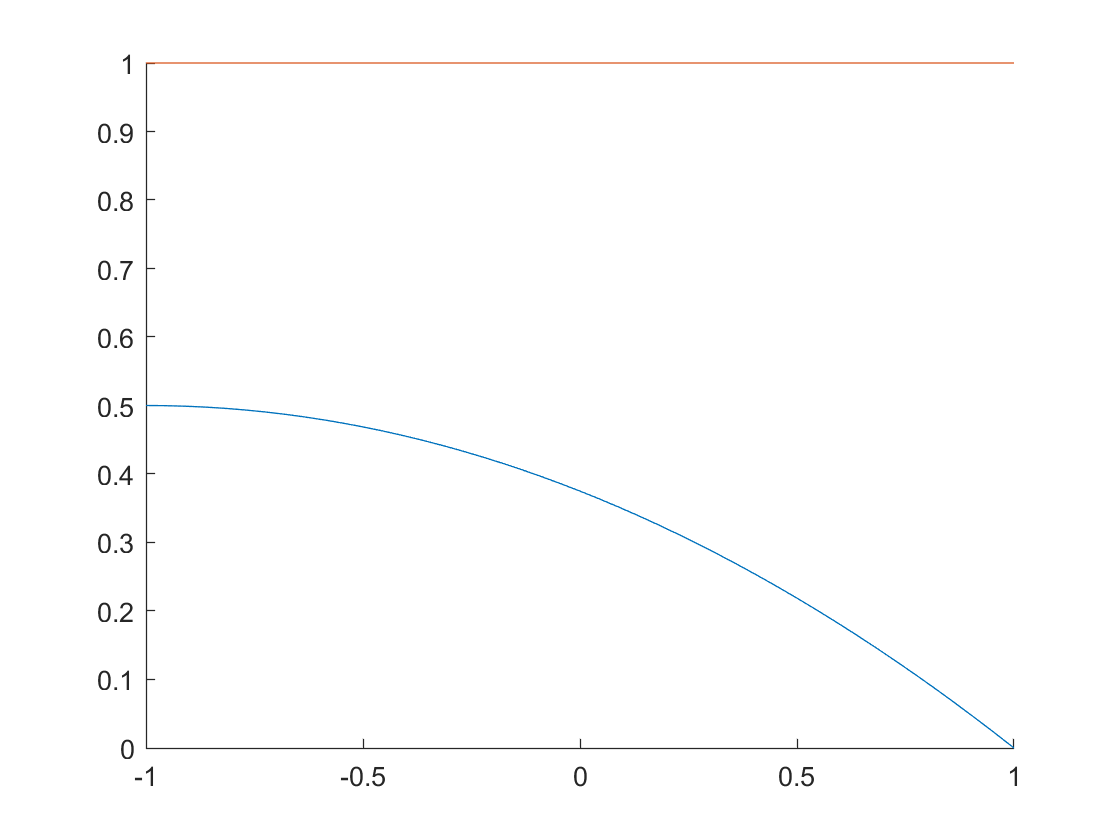

% for e = 1:nElem
%     localExactSolution = ELEM(e).Global_to_LocalVariate;
%     err(e) = int(exactSolution * ELEM(e).LApproxSolution,ELEM(e).LDomain)
% end

ylim([0 1])

clear

exactSolution = computeExactSolution(1)

exactSolution = struct with fields:
         f: 1
       eqn: [1×1 symfun]
      cond: [1×2 sym]
    domain: [0 1]
         U: [1×1 symfun]



for n = 1:4
    xMin = 0;
    xMax = 1;
    nELEM = n;
    eDegree = 1;
    
    % Case A
    
    feSolution = main(nELEM,eDegree,1);
    
    ELEM = feSolution.Elements;
    err(n) = sym(0);
    for e = 1:nELEM
        localExactSolution = exactSolution.U(ELEM(e).LocalVariate_to_GlobalVariate);
        localApproxSolution = ELEM(e).LBasisFuns' * ELEM(e).LDOF;
        
        err(n) = err(n) + int((localExactSolution - localApproxSolution)^2 * diff(ELEM(e).LocalVariate_to_GlobalVariate) , ELEM(e).LDomain);
    end
end
err

$$err = \left(\begin{array}{cccc} \frac{7}{15} & \frac{7}{15} & \frac{7}{15} & \frac{7}{15} \end{array}\right)$$

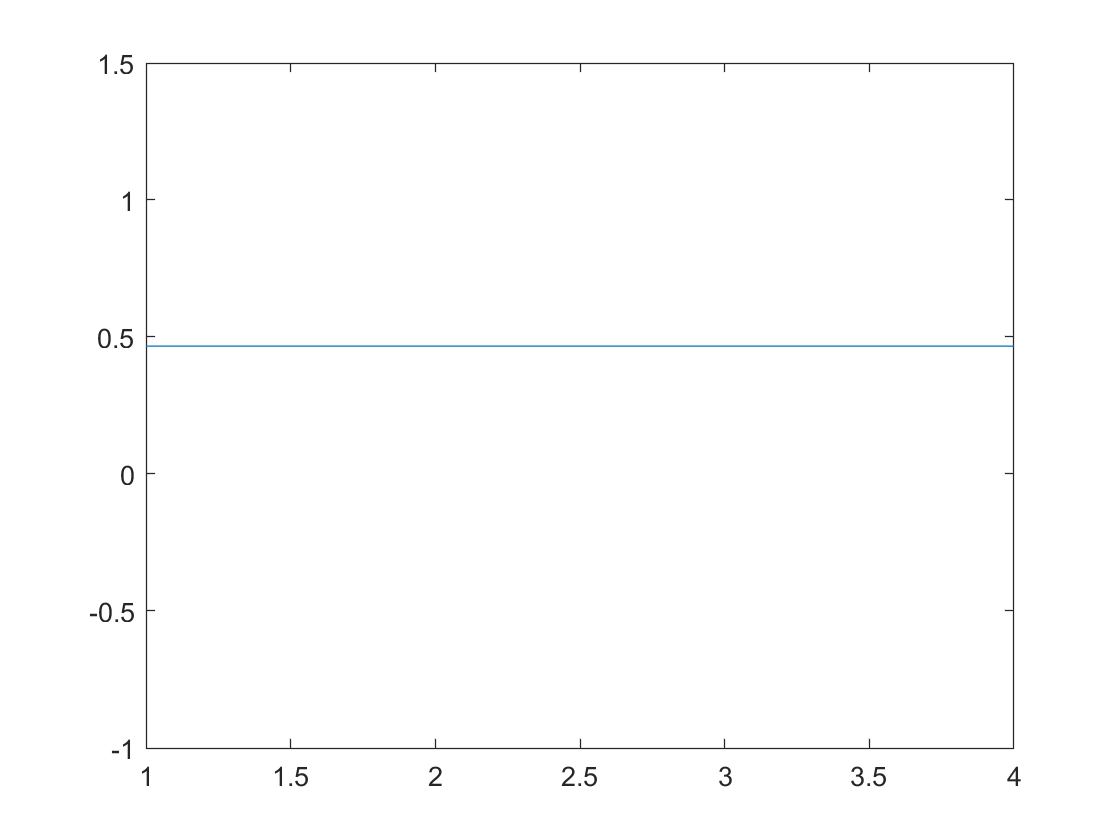


figure
plot(err)

clear
exactSolution = computeExactSolution(1)

exactSolution = struct with fields:
         f: 1
       eqn: [1×1 symfun]
      cond: [1×2 sym]
    domain: [0 1]
         U: [1×1 symfun]



for n = 1:4
    xMin = 0;
    xMax = 1;
    nELEM = n;
    eDegree = 1;
    
    % Case A
    
    feSolution = main(nELEM,eDegree,1);
    err = computeError(exactSolution,feSolution,"Exact")
    err = computeError(exactSolution,feSolution,"Gauss-Quadrature")
    
end

$$err = \frac{\sqrt{105}}{15}$$

$$err = \frac{\sqrt{105}}{15}$$

$$err = \frac{\sqrt{8490}}{240}+\frac{\sqrt{18390}}{240}$$

$$err = \frac{\sqrt{8490}}{240}+\frac{\sqrt{18390}}{240}$$

$$err = \frac{\sqrt{1635}}{135}+\frac{\sqrt{9690}}{270}+\frac{\sqrt{17790}}{270}$$

$$err = \frac{\sqrt{1635}}{135}+\frac{\sqrt{9690}}{270}+\frac{\sqrt{17790}}{270}$$

$$err = \frac{7\,\sqrt{3705}}{960}+\frac{\sqrt{60045}}{960}+\frac{\sqrt{75795}}{960}+\frac{\sqrt{112695}}{960}$$

$$err = \frac{7\,\sqrt{3705}}{960}+\frac{\sqrt{60045}}{960}+\frac{\sqrt{75795}}{960}+\frac{\sqrt{112695}}{960}$$